# **EJERCICIO DE REPASO SIMULACIÓN CONTINUA **

## **Enunciado**

Como se acercan las Navidades, estás pensando en comprar a tu prima pequeña una de las muñecas de moda entre la población de su edad. En particular, estás interesado en comprar la muñeca Draculaura, de la colección Monster High. Has estado revisando el precio y actualmente esta muñeca, junto con su complemento, cuesta aproximadamente 30€.

Para comprobar cuál es el mejor momento de compra, quieres estudiar la evolución del precio en los próximos 10 días en la tienda de tu barrio, teniendo en cuenta que el precio de cualquier producto varía en función de la oferta y demanda de dicho producto, en este caso en particular, la demanda de Draculaura. Conoces el modelo que define la variación del precio en función de la oferta y la demanda de cada día (t), que es la siguiente:

dP / dt = k * (d(t) - o(t))


$$\frac{\textrm{dP}}{dt }\;=\;k\;\cdot \left(d\left(t\right)-o\left(t\right)\right)$$


Siendo P la variable que indica el precio de Draculaura, k una constante de proporcionalidad, d la cantidad de

muñecas demandadas y o la cantidad de muñecas disponibles en la tienda bajo estudio.

Además, conoces que tanto la oferta como la demanda dependen del precio del producto en la mayoría de ocasiones. En particular, la oferta es **inversamente** proporcional al precio de un producto, mientras que la demanda es **directamente** proporcional. Ambas variables pueden escribirse en función del precio de la siguiente forma:

d(t) = d1 + d2 * P(t) ; d2 < 0

o(t) = o1 + o2 * P(t) ; 02 > 0


$$d\left(t\right)=d_{1\;} +\;d_{2\;} \cdot \;P\left(t\right);{\;d}_{2\;} <0$$



$$o\left(t\right)=o_1 +o_{2\;} \cdot P\left(t\right);o_{2\;} >0$$


### **Preguntas**

### **1. Define el modelo a simular: **

    Vamos a tratar este ejercicio como un problema de simulación continua. Primero vamos a definir las variables necesarias para poder hacer el modelo del problema: 

**Variable de estado: **


$$\textrm{Precio}\;\textrm{de}\;\textrm{la}\;\textrm{muñeca}=P\;$$


**Variables: **


$$\begin{array}{l}
\textrm{demanda}=d\;\\
\textrm{oferta}=o\;\\
\textrm{constante}=k\;\\
\textrm{Tasa}\;\textrm{de}\;\textrm{variación}\;\textrm{del}\;\textrm{tiempo}=\textrm{dt}\;\\
\textrm{Tiempo}\;\textrm{Total}=T\;
\end{array}$$


**Transiciones: **


$$P\left(t\right)=k\cdot \left\lbrack \left(d_{1\;} +\;d_{2\;} \cdot P\left(t\right)\right)-\left(o_1 +o_{2\;} \cdot P\left(t\right)\right)\right\rbrack$$


Usando la definición de límite podemos hallar P(t + dt): 


$$P\left(t\right)=\;\lim_{\textrm{dt}\to 0} \;\frac{P\left(t+\textrm{dt}\;\right)-P\left(t\right)}{\textrm{dt}}$$



$$k\cdot \left\lbrack \left(d_{1\;} +\;d_{2\;} \cdot P\left(t\right)\right)-\left(o_1 +o_{2\;} \cdot P\left(t\right)\right)\;\right\rbrack =\frac{P\left(t+\textrm{dt}\;\right)-P\left(t\right)}{\textrm{dt}}\;$$



$$P\left(t+\textrm{dt}\;\right)\;-\;P\left(t\right)=\;\textrm{dt}\cdot k\cdot \left\lbrack \left(d_{1\;} +\;d_{2\;} \cdot P\left(t\right)\right)-\left(o_1 +o_{2\;} \cdot P\left(t\right)\right)\right\rbrack$$


### 2. Estudia la estabilidad del precio:

La estabilidad del precio se define como:$P\left(t\right)=P\left(t+\textrm{dt}\right)\Rightarrow P\left(t\right)-P\left(t-\textrm{dt}\right)=0$

clc,clear, clf 

syms precio d1 d2 o1 o2 dt k 

ecuacion = dt * k * ((d1 + d2*precio) - (o1 + o2*precio))  == 0

$$ecuacion = \mathrm{dt}\,k\,\left(d_{1}-o_{1}+d_{2}\,\mathrm{precio}-o_{2}\,\mathrm{precio}\right)=0$$

solucion = solve( ecuacion, precio )

$$solucion = -\frac{d_{1}-o_{1}}{d_{2}-o_{2}}$$


$$\textrm{dt}\cdot k\cdot \left\lbrack \left(d_{1\;} +\;d_{2\;} \cdot P\left(t\right)\right)-\left(o_1 +o_{2\;} \cdot P\left(t\right)\right)\right\rbrack =0\;$$



$$\begin{array}{l}
\textrm{dt}=0\;\;\\
k=0\;\;\\
\left\lbrack \left(d_{1\;} +\;d_{2\;} \cdot P\left(t\right)\right)-\left(o_1 +o_{2\;} \cdot P\left(t\right)\right)\right\rbrack =0\;\;\Rightarrow \textrm{vamos}\;a\;\textrm{estudiar}
\end{array}$$



$$\left(d_{1\;} -o_1 \;\right)+\left(d_{2\;} -o_{2\;} \right)\cdot P\left(t\right)=0$$


La **estabilidad** del precio viene definida por : 


$$P\left(t\right)=-\;\frac{\left(d_{1\;} -o_1 \right)}{\left(d_{2\;} -o_{2\;} \right)}$$


Con está información podemos ver los diferentes casos para ver la variación del precio. Como la contante $k$ no afecta a la estabilidad del precio le daremos siempre el mismo valor $k=1$. Por lo tanto, trabajaremos con los valores de la demanda y oferta.

#### Caso 1 

La forma trivial de conseguir la estabailidad del precio es que no haya demanda ni oferta. 


$$\left\lbrace \begin{array}{ll}
\left(d_{1\;} -o_1 \right)=0 & \\
\left(d_{2\;} -o_{2\;} \right)=0 & 
\end{array}\right.$$


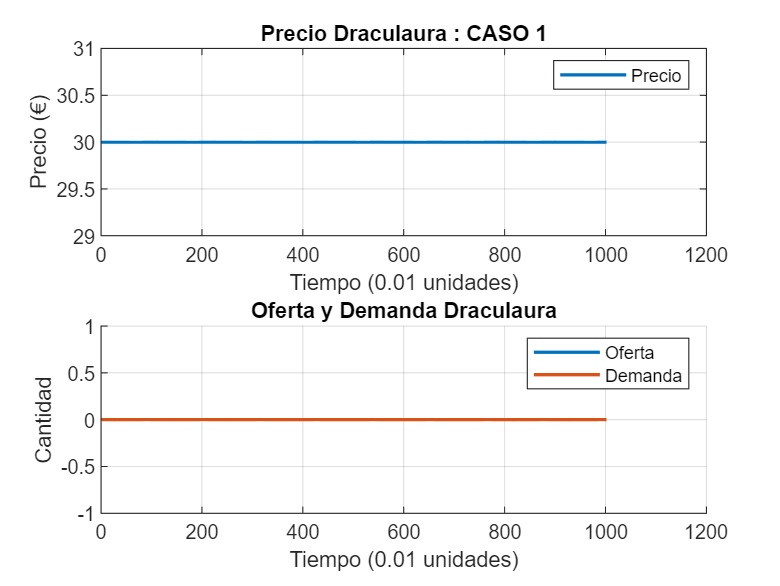

clc, clear, clf

% Variable de estado  
P0 = 30;

% Tiempo 
dt = 0.01; 
T = 10;

%variables
d1 = 0;
d2 = 0; % > 0 
o1 = 0;
o2 = 0; % < 0 
k = 1;

% Simulación 
[precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0);

% Dibujamos las gráficas
figure
subplot(2, 1, 1)
plot(precio, 'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Precio (€)")
title("Precio Draculaura : CASO 1")
legend('Precio')
grid on
subplot(2, 1, 2)
hold on
plot(oferta, 'LineWidth', 1.5)
plot(demanda,'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Cantidad")
title("Oferta y Demanda Draculaura")
legend('Oferta', 'Demanda')
grid on
hold off


fprintf('Valor de Draculaura pasados 10 dias: %.4f €', precio(end))

Valor de Draculaura pasados 10 dias: 30.0000 €

#### Caso 2

La estabilidad del precio también viene dada por:


$$P\left(t\right)=-\;\frac{\left(d_{1\;} -o_1 \right)}{\left(d_{2\;} -o_{2\;} \right)}\Rightarrow -\left(d_{1\;} -o_1 \right)=\left(d_{2\;} -o_{2\;} \right)$$


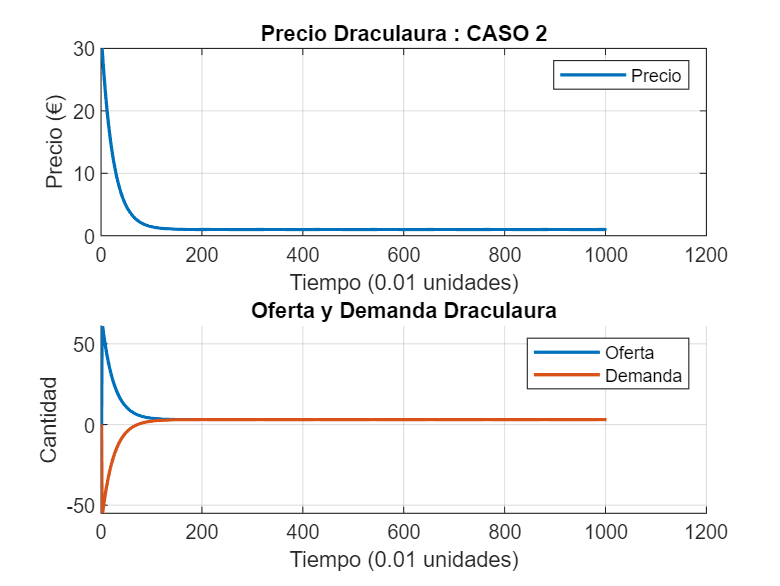

clc, clear, clf

% Variable de estado  
P0 = 30;

% Tiempo 
dt = 0.01; 
T = 10;

%variables
d1 = 5;
d2 = -2; % > 0 
o1 = 1;
o2 = 2; % < 0 
k = 1;

% Simulación 
[precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0);

% Dibujamos las gráficas
figure
subplot(2, 1, 1)
plot(precio, 'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Precio (€)")
title("Precio Draculaura : CASO 2")
legend('Precio')
grid on
subplot(2, 1, 2)
hold on
plot(oferta, 'LineWidth', 1.5)
plot(demanda,'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Cantidad")
title("Oferta y Demanda Draculaura")
legend('Oferta', 'Demanda')
grid on
hold off


fprintf('Valor de Draculaura pasados 10 dias: %.4f €', precio(end))

Valor de Draculaura pasados 10 dias: 1.0000 €

#### Caso 3


$$\left(d_{1\;} -o_1 \right)=\left(d_{2\;} -o_{2\;} \right)\;$$


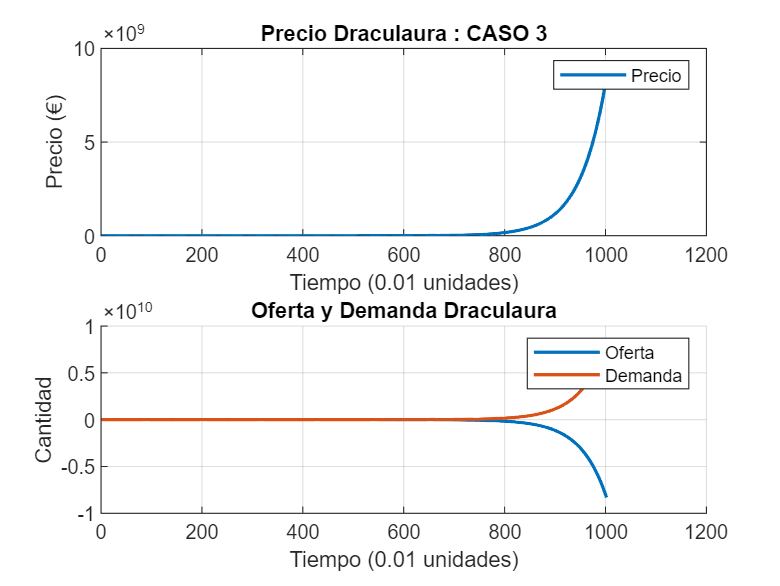

clc, clear, clf

% Variable de estado  
P0 = 30;

% Tiempo 
dt = 0.01; 
T = 10;

%variables
d1 = 1;
d2 = 1; % > 0 
o1 = -1;
o2 = -1; % < 0 
k = 1;

% Simulación 
[precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0);

% Dibujamos las gráficas
figure
subplot(2, 1, 1)
plot(precio, 'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Precio (€)")
title("Precio Draculaura : CASO 3")
legend('Precio')
grid on
subplot(2, 1, 2)
hold on
plot(oferta, 'LineWidth', 1.5)
plot(demanda,'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Cantidad")
title("Oferta y Demanda Draculaura")
legend('Oferta', 'Demanda')
grid on
hold off

fprintf('Valor de Draculaura pasados 10 dias: %.4f €', precio(end))

Valor de Draculaura pasados 10 dias: 8469184350.2142 €

#### Caso 4 


$$\left(d_{1\;} -o_1 \right)>\left(d_{2\;} -o_{2\;} \right)\;$$


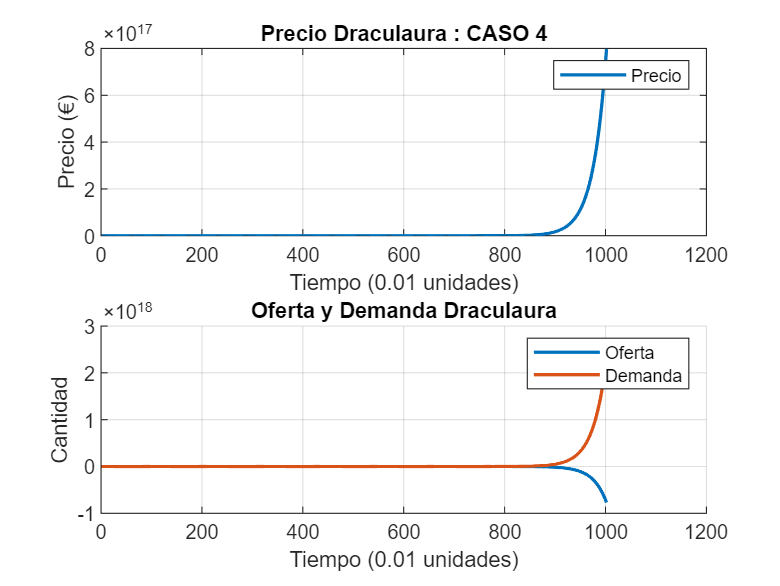

clc, clear, clf

% Variable de estado  
P0 = 30;

% Tiempo 
dt = 0.01; 
T = 10;

%variables
d1 = 2;
d2 = 3; % > 0 
o1 = -1;
o2 = -1; % < 0 
k = 1;

% Simulación 
[precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0);

% Dibujamos las gráficas
figure
subplot(2, 1, 1)
plot(precio, 'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Precio (€)")
title("Precio Draculaura : CASO 4")
legend('Precio')
grid on
subplot(2, 1, 2)
hold on
plot(oferta, 'LineWidth', 1.5)
plot(demanda,'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Cantidad")
title("Oferta y Demanda Draculaura")
legend('Oferta', 'Demanda')
grid on
hold off

fprintf('Valor de Draculaura pasados 10 dias: %.4f €', precio(end))

Valor de Draculaura pasados 10 dias: 797693151563467904.0000 €

#### Caso 5


$$\left(d_{1\;} -o_1 \right)<\left(d_{2\;} -o_{2\;} \right)\;$$


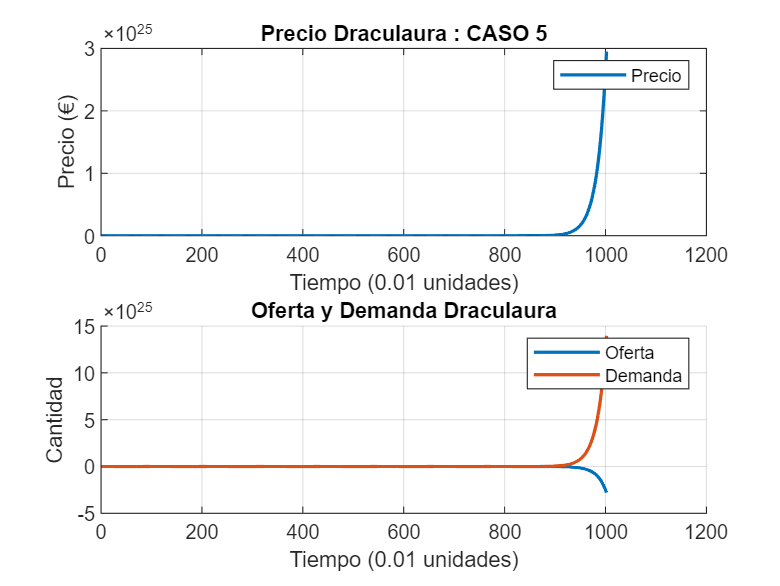

clc, clear, clf

% Variable de estado  
P0 = 30;

% Tiempo 
dt = 0.01; 
T = 10;

%variables
d1 = 3;
d2 = 5; % > 0 
o1 = -0.5;
o2 = -1; % < 0 
k = 1;

% Simulación 
[precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0);

% Dibujamos las gráficas
figure
subplot(2, 1, 1)
plot(precio, 'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Precio (€)")
title("Precio Draculaura : CASO 5")
legend('Precio')
grid on
subplot(2, 1, 2)
hold on
plot(oferta, 'LineWidth', 1.5)
plot(demanda,'LineWidth', 1.5)
xlabel("Tiempo (0.01 unidades)")
ylabel("Cantidad")
title("Oferta y Demanda Draculaura")
legend('Oferta', 'Demanda')
grid on
hold off

fprintf('Valor de Draculaura pasados 10 dias: %.4f €', precio(end))

Valor de Draculaura pasados 10 dias: 29502658365727331357556736.0000 €

## Funciones

function [precio, oferta, demanda] = valores(d1,d2,o1,o2,k,dt,T,P0)
    t = 0;
    i = 1;
    % variable de estado.
    precio = [P0];

    % Variables
    demanda = [];
    oferta = [];


    while t < T
    i = i + 1;

    % criterio de parada
    t = t + dt; 
    
    %Rutina de evento
    demanda(i) = d1 + d2 * precio(i - 1);
    oferta(i) = o1 + o2 * precio(i - 1);

    precio(i) = precio(i - 1) + dt * k * ( demanda(i-1) - oferta(i-1) );
    end
end